In this project, I have used a Basic Kalman filter and an Unscented Kalman Filter to track a cricket ball in three dimensions. The ball can bounce off the pitch and can also spin after the bounce. We have a camera to record the ball's position from the top and another camera to record the position from the side every 0.01 seconds. The positions obtained from the camera  have significant measurement errors. In the last part, I have also introduced a ball swing to demonstrate the non-linear tracking capability of Unscented Kalman Filter. 

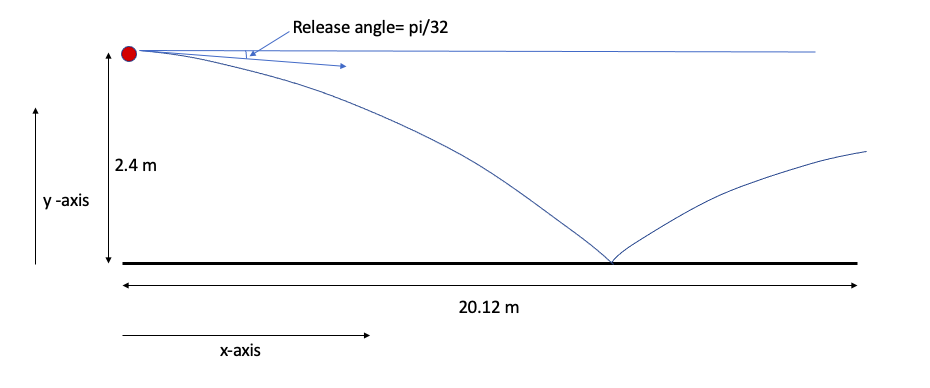

                                        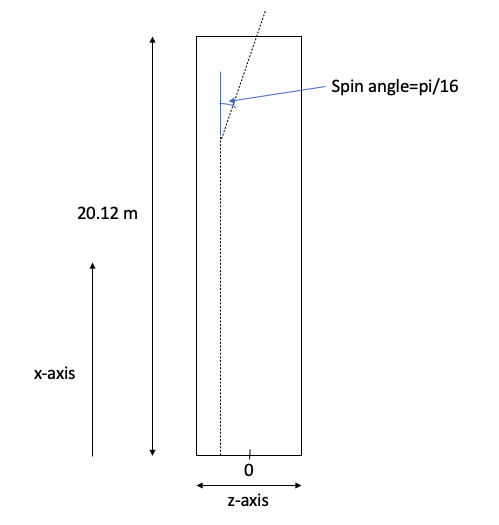

The following assumptions have been made-

- The bowler releases the ball at an angle along the axis parallel to the ground at an initial velocity of 125 km/h or 33.33 m/s. We have fixed this angle at pi/32.

- The ball is released from a height of 2.4 m. (The point of release is 2.4 m above the surface ) 

- The time taken by the ball to cross the pitch is not expected to be more than 2 seconds.

- x-axis is the axis along the pitch

- y-axis is prependicular to the x-axis and directed towards the sky. So, gravity will act along this direction.

- z-axis is along the width of the pitch. So, the action of spin will be visible along this axis.

- The bounce introduces a spin which can be seen from top camera. The spin angle is taken to be pi/16 as shown in the above image. 

- It is also assumed that there is no loss of energy on bounce. Only the direction of motion is reversed along the y-axis.

- In the last part, the ball can swing in the air towards the right side. The amount of swing is a function of square of distance from the point of release

PART 1: Basic Kalman filter

% Tracking a cricket ball using the Basic Kalman filtering algorithm.
% The bowler releases the ball at an angle of pi/32 to the 
% ground at a velocity of 125 km/h or 33.33 m/s

clear;clc;
rng('shuffle')

%Length of a cricket pitch is around 20.12 m, also a ball
%duration is not expected to be more than 2 seconds

deltaT=0.01; %fixed time step
g=-9.81; %accleration due to gravity
F1 = [1 deltaT 0 0 0 0;0 1 0 0 0 0;0 0 1 deltaT 0 0;0 0 0 1 0 0;0 0 0 0 1 deltaT;0 0 0 0 0 1]; %transition matrix
B=[0 0 0 0 0 0;0 0 0 0 0 0;0 0 1 0 0 0;0 0 0 1 0 0;0 0 0 0 0 0;0 0 0 0 0 0]; %matrix for control vector
un=[0 0 (1/2)*g*(deltaT)^2 g*deltaT 0 0]'; %control vector


F=F1;
Ft = inv(F);
C = [1 0 0 0 0 0;0 1 0 0 0 0;0 0 1 0 0 0;0 0 0 1 0 0; 0 0 0 0 1 0; 0 0 0 0 0 1]; %measurement matrix
sigma_v1 = 0.01; %process noise is zero in this case
Q1 = sigma_v1*eye(6);%process noise correlation matrix
sigma_v2 =0.1; %measurement noise
Q2 = sigma_v2*eye(6);%measurement noise correlation matrix

%Let's generate some observations.
%Ball is released at an angle of pi/32 from
%a height of 2.4 meters (taking point of release as 2.4 m 
%above the surface). For a bowler, taking initial 
% speed of ball at release to be 125 km/h or 33.33 m/s
%Taking intial release point to be -1 m to the left
%from the center or wickets. So, initial z position = -1 m.

x(:,1)=[0 33.33*cos(pi/32) 2.4 -33.33*sin(pi/32) -1 0]';
x_clean(:,1)=x;
%xx(:,1)=x(:,1);
y = zeros(6,200);

for i=1:200
    x(:,i+1) = F1 * x(:,i) + B*un+sigma_v1*randn(6,1);
    y(:,i) = C*x(:,i) + sqrt(sigma_v2)*randn(6,1);
    if x(3,i+1) < 0 %checking for bounce
        x(3,i+1)=0;
        x(4,i+1)=-1*x(4,i+1); %Ball changes direction in y-axis 
        %Taking amount of spin to be pi/16 to the z-axis
        %We are taking spin to be in the right direction
        x(2,i+1)=x(2,i+1)*cos(pi/16);
        x(6,i+1)=x(2,i+1)*sin(pi/16);
    end
    
end


% Now let's use the Kalman filter to track the state.

%initial estimate of the state
%Giving y a value of 10 and z to be 0 to check how 
% quickly algoritm adjusts
xhat(:,1)=[0 33.33*cos(pi/32) 10 -33.33*sin(pi/32) 0 0]'; 

%Initial estimate of the filtered error correlation matrix
Kn=eye(6);

%onto Kalman filtering

for i = 1:200
    G = F * Kn * C' * inv(C*Kn*C' + Q2);
    alpha(:,i) = y(:,i) - C*xhat(:,i);
    xhat(:,i+1) = F*xhat(:,i) + G*alpha(:,i)+B*un;
    myx(:,i)=F*xhat(:,i+1);
    K = Kn - Ft * G * C * Kn;
    Kn = F * K * F' + Q1;

end

%Plot for bounce estimation
plot(x(1,:),x(3,:));hold;plot(y(1,:),y(3,:),'*');plot(xhat(1,:),xhat(3,:),'--o');hold

Current plot held


Current plot released


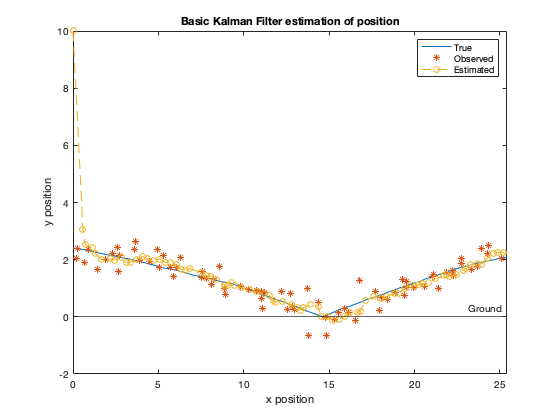

xlabel('x position');ylabel('y position');title('Basic Kalman Filter estimation of position');
legend('True','Observed','Estimated','AutoUpdate','off');
xlim([0 21])
yline(0,'-','Ground');


%Plot for spin estimation
plot(x(5,:),x(1,:));hold;plot(y(5,:),y(1,:),'*');plot(xhat(5,:),xhat(1,:),'-o');hold

Current plot held


Current plot released


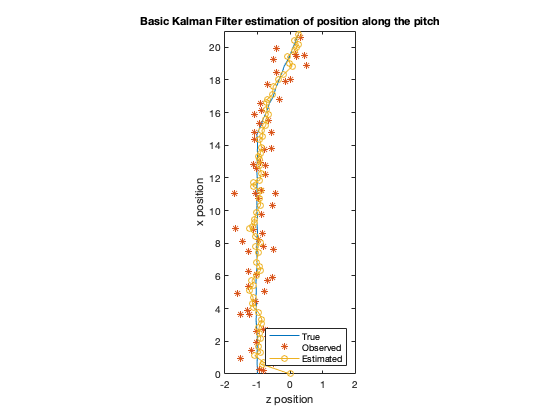

xlabel('z position');ylabel('x position');title('Basic Kalman Filter estimation of position along the pitch');
legend('True','Observed','Estimated','Location','southeast');
xlim([-2 2])
set(gca, 'XTick', -2:2)
ylim([0 21])
daspect([1,2,2])

It can be seen that we are able to track the ball using Basic Kalman Filter with some error.

But a Basic Kalman Filter is limited to linear equations. When our equations are non-linear then we can use Extended Kalman Filter (EKF) and Unscented Kalman Filter (UKF). 

EKF has many drawbacks like Jacobians can be difficult to calculate, there can be a high computational cost and it is not optimal if the system is highly non-linear. 

So, we will first implememt Unscented Kalman Filter for the same system.

PART 2: Unscented Kalman filter

% Tracking a cricket ball using the Unscented 
% Kalman filtering algorithm.
% The bowler releases the ball at an angle of pi/32 to the 
% ground at a velocity of 125 km/h or 33.33 m/s

clear;clc;
rng('shuffle')

%Length of a cricket pitch is around 20.12 m, also a ball
%duration is not expected to be more than 2 seconds

deltaT=0.01; %fixed time step
g=-9.81; %accleration due to gravity
F1 = [1 deltaT 0 0 0 0;0 1 0 0 0 0;0 0 1 deltaT 0 0;0 0 0 1 0 0;0 0 0 0 1 deltaT;0 0 0 0 0 1]; %transition matrix
B=[0 0 0 0 0 0;0 0 0 0 0 0;0 0 1 0 0 0;0 0 0 1 0 0;0 0 0 0 0 0;0 0 0 0 0 0]; %matrix for control vector
un=[0 0 (1/2)*g*(deltaT)^2 g*deltaT 0 0]'; %control vector


F=F1;
Ft = inv(F);
C = [1 0 0 0 0 0;0 1 0 0 0 0;0 0 1 0 0 0;0 0 0 1 0 0; 0 0 0 0 1 0; 0 0 0 0 0 1]; %measurement matrix
sigma_v1 = 0.01; %process noise is zero in this case
Q1 = sigma_v1*eye(6);%process noise correlation matrix
sigma_v2 =0.1; %measurement noise
Q2 = sigma_v2*eye(6);%measurement noise correlation matrix

%Let's generate some observations.
%Ball is released at an angle of pi/32 from
%a height of 2.4 meters (taking point of release as 2.4 m 
%above the surface). For a bowler, taking initial 
% speed of ball at release to be 125 km/h or 33.33 m/s
%Taking intial release point to be -1 m to the left
%from the center or wickets. So, initial z position = -1 m.

x(:,1)=[0 33.33*cos(pi/32) 2.4 -33.33*sin(pi/32) -1 0]';


y = zeros(6,200);

for i=1:200
    x(:,i+1) = F1 * x(:,i) + B*un+sigma_v1*randn(6,1);
    y(:,i) = C*x(:,i) + sqrt(sigma_v2)*randn(6,1);
    if x(3,i+1) < 0 %checking for bounce
        x(3,i+1)=0;
        x(4,i+1)=-1*x(4,i+1); %Ball changes direction in y-axis 
        %Taking amount of spin to be pi/16 to the z-axis
        %We are taking spin to be in the right direction
        x(2,i+1)=x(2,i+1)*cos(pi/16);
        x(6,i+1)=x(6,i+1)+x(2,i+1)*sin(pi/16);
    end
    
end


% Now let's use the Unscented Kalman filter to 
% track the state.

%initial estimate of the state
%Giving y a value of 10 and z to be 0 to check how 
% quickly algoritm adjusts
xhat(:,1)=[0 33.33*cos(pi/32) 10 -33.33*sin(pi/32) 0 0]'; 

%Initial estimate of the filtered error correlation matrix
Kn=eye(6);

%onto Unscented Kalman filtering

for i = 1:200  
    L=numel(x(:,i));                                 %number of states
    m=numel(y(:,i));                                 %number of measurements
    lambda=3-L;                      %scaling factor,Taking lambda = 3-number of states
    c=L+lambda;                                 %scaling factor
    Wm=[lambda/c 0.5/c+zeros(1,2*L)];           %weights for means, total 13 weights will be genearted
    Wc=Wm;                                      %weights for covariance, again 13 weights generated               
    X=sigmas(xhat(:,i),Kn,c);                     %getting sigma points, we will get 13 sigma points
    
    %Going for unscented transformation. We will get the following vales- 
    %For process state space we have-
    %x1=transformed mean
    %X1=transformed smapling points (in non linear systems)
    %P1=transformed covariance
    %X2=transformed deviations
    
    %Similarly, for measurement space we have-
    %z1=transformed mean
    %Z1=transformed smapling points (in non linear systems)
    %P2=transformed covariance
    %Z2=transformed deviations   

    [x1,X1,P1,X2]=ut(X,Wm,Wc,L,Q1);          %unscented transformation of process
    [z1,Z1,P2,Z2]=ut(X1,Wm,Wc,m,Q2);       %unscented transformation of measurments  
    Pcross=X2*diag(Wc)*Z2';                   %transformed cross-covariance
    K=Pcross*inv(P2);                       %Calculating Kalman gain
    xhat(:,i+1)=x1+K*(y(:,i)-z1);          %state update
    Kn=P1-K*P2*K';                         %covariance update

end

%Plot for bounce estimation
plot(x(1,:),x(3,:));hold;plot(y(1,:),y(3,:),'*');plot(xhat(1,:),xhat(3,:),'-o');hold

Current plot held


Current plot released


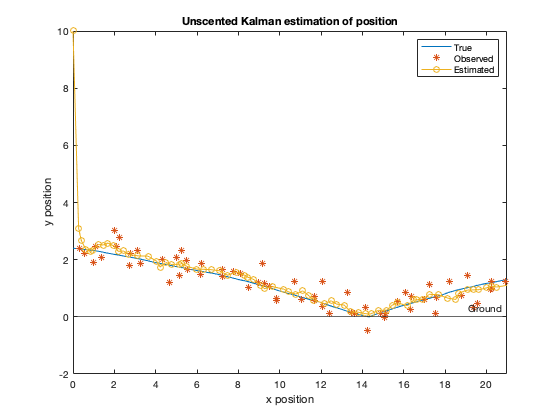

xlabel('x position');ylabel('y position');title('Unscented Kalman estimation of position');
legend('True','Observed','Estimated','AutoUpdate','off');
xlim([0 21])
yline(0,'-','Ground');


%Plot for spin estimation
plot(x(5,:),x(1,:));hold;plot(y(5,:),y(1,:),'*');plot(xhat(5,:),xhat(1,:),'-o');hold

Current plot held


Current plot released


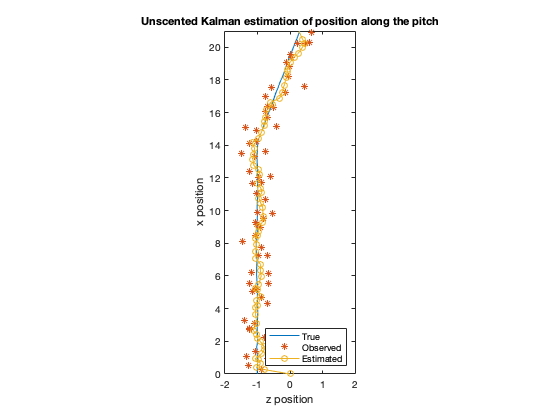

xlabel('z position');ylabel('x position');title('Unscented Kalman estimation of position along the pitch');
legend('True','Observed','Estimated','Location','southeast');
xlim([-2 2])
set(gca, 'XTick', -2:2)
ylim([0 21])
daspect([1,2,2])

As we can see, we are able to track the ball using UKF with a decent level of accuracy. UKF can be particularly useful if we have non-linearities in our system as these can not be handled by a Basic Kalman Filter.

PART 3: Unscented Kalman filter with ball swing

Let us now introduce a non-linearity in our problem. We will introduce a non-linear swing of the ball in the system such that the amount of swing is a function of square of distance from the point of release. So, a ball swings more rapidly as it gets farther away along the pitch. The effect of swing will be visible along the z-axis. We have assumed that this swing deviates the ball in the air to the right side.

% Tracking a cricket ball with non-linearty using the Unscented 
% Kalman filtering algorithm.
% The bowler releases the ball at an angle of pi/32 to the 
% ground at a velocity of 125 km/h or 33.33 m/s

clear;clc;
rng('shuffle')

%Length of a cricket pitch is around 20.12 m, also a ball
%duration is not expected to be more than 2 seconds

deltaT=0.01; %fixed time step
g=-9.81; %accleration due to gravity
F1 = [1 deltaT 0 0 0 0 0;0 1 0 0 0 0 0;0 0 1 deltaT 0 0 0;0 0 0 1 0 0 0;0 0 0 0 1 deltaT 1;0 0 0 0 0 1 0;0 0 0 0 0 0 1]; %transition matrix
B=[0 0 0 0 0 0;0 0 0 0 0 0;0 0 1 0 0 0;0 0 0 1 0 0;0 0 0 0 0 0;0 0 0 0 0 0]; %matrix for control vector
un=[0 0 (1/2)*g*(deltaT)^2 g*deltaT 0 0]'; %control vector


F=F1;
Ft = inv(F);
C = [1 0 0 0 0 0 0;0 1 0 0 0 0 0;0 0 1 0 0 0 0;0 0 0 1 0 0 0; 0 0 0 0 1 0 0; 0 0 0 0 0 1 0; 0 0 0 0 0 0 1]; %measurement matrix
sigma_v1 = 0.01; %process noise is zero in this case
Q1 = sigma_v1*eye(7);%process noise correlation matrix
sigma_v2 =0.1; %measurement noise
Q2 = sigma_v2*eye(7);%measurement noise correlation matrix


swg=0.00015;          %this controls the amount of swing
y = zeros(7,200);
f=@(x)[x(1);x(2);x(3);x(4);x(5);x(6);swg*(x(1)^2)]; %state equation
h=@(y)[y(1);y(2);y(3);y(4);y(5);y(6);y(7)]; 


%Let's generate some observations.
%Ball is released at an angle of pi/32 from
%a height of 2.4 meters (taking point of release as 2.4 m 
%above the surface). For a bowler, taking initial 
% speed of ball at release to be 125 km/h or 33.33 m/s
%Taking intial release point to be -1 m to the left
%from the center or wickets. So, initial z position = -1 m.

x(:,1)=[0 33.33*cos(pi/32) 2.4 -33.33*sin(pi/32) -1 0 0]';

for i=1:200 
    F2=F1 * x(:,i);
    x(1:6,i+1) = F2(1:6) + B*un+sigma_v1*randn(6,1);
    x(7,i+1) = swg*(x(1,i+1)^2) +sigma_v1*randn(1,1); %updating swing factor in state
    y(:,i) = C*x(:,i) + sqrt(sigma_v2)*randn(7,1);
    if x(3,i+1) < 0 %checking for bounce
        x(3,i+1)=0;
        x(4,i+1)=-1*x(4,i+1); %Ball changes direction in y-axis 
        %Taking amount of spin to be pi/16 to the z-axis
        %We are taking spin to be in the right direction
        x(2,i+1)=x(2,i+1)*cos(pi/16);
        x(6,i+1)=x(6,i+1)+x(2,i+1)*sin(pi/16);
    end
    
end


% Now let's use the Unscented Kalman filter to 
% track the state.

%initial estimate of the state
%Giving y a value of 10 and z to be 0 to check how 
% quickly algoritm adjusts
xhat(:,1)=[0 33.33*cos(pi/32) 10 -33.33*sin(pi/32) 0 0 0]'; 

%Initial estimate of the filtered error correlation matrix
Kn=eye(7);

%onto Kalman filtering

for i = 1:200  
    L=numel(x(:,i));                                 %number of states
    m=numel(y(:,i));                                 %number of measurements
    lambda=3-L;                      %scaling factor,Taking lambda = 3-number of states
    c=L+lambda;                                 %scaling factor
    Wm=[lambda/c 0.5/c+zeros(1,2*L)];           %weights for means, total 15 weights will be genearted
    Wc=Wm;                                      %weights for covariance, again 15 weights generated               
    X=sigmas(xhat(:,i),Kn,c);                     %sigma points around x, 15 sigma points
    %Going for unscented transformation. We will get the following vales- 
    %For process state space we have-
    %x1=transformed mean
    %X1=transformed smapling points (in non linear systems)
    %P1=transformed covariance
    %X2=transformed deviations
    
    %Similarly, for measurement space we have-
    %z1=transformed mean
    %Z1=transformed smapling points (in non linear systems)
    %P2=transformed covariance
    %Z2=transformed deviations   

    
    [x1,X1,P1,X2]=ut_nl(f,X,Wm,Wc,L,Q1);          %unscented transformation of process
    [z1,Z1,P2,Z2]=ut_nl(h,X1,Wm,Wc,m,Q2);       %unscented transformation of measurments  
    Pcross=X2*diag(Wc)*Z2';                   %transformed cross-covariance
    K=Pcross*inv(P2);
    xhat(:,i+1)=x1+K*(y(:,i)-z1);          %state update 
    Kn=P1-K*P2*K'; 

end

%Plot for bounce estimation
plot(x(1,:),x(3,:));hold;plot(y(1,:),y(3,:),'*');plot(xhat(1,:),xhat(3,:),'-o');hold

Current plot held


Current plot released


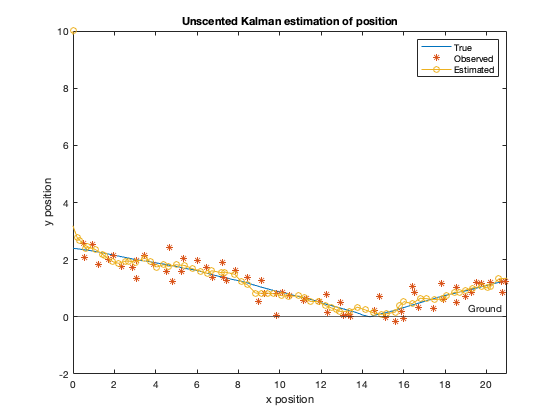

xlabel('x position');ylabel('y position');title('Unscented Kalman estimation of position');
legend('True','Observed','Estimated','AutoUpdate','off');
xlim([0 21])
yline(0,'-','Ground');


%Plot for spin and swing estimation
plot(x(5,:),x(1,:));hold;plot(y(5,:),y(1,:),'*');plot(xhat(5,:),xhat(1,:),'-o');hold

Current plot held


Current plot released


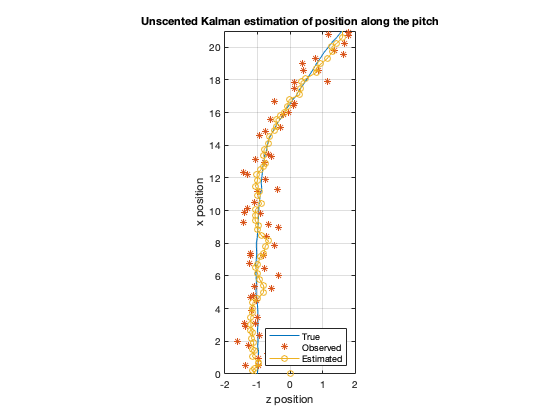

xlabel('z position');ylabel('x position');title('Unscented Kalman estimation of position along the pitch');
legend('True','Observed','Estimated','Location','southeast');
xlim([-2 2])
set(gca, 'XTick', -2:2)
ylim([0 21])
daspect([1,2,2])
grid on

As can be seen in the plot, this time the ball curves towards the right side in the air due to a non-linear swing. It curves more as it moves away from the point of release. We are still able to track it using an Unscented Kalman Filter with a decent level of accuracy.

Used functions are defined below-

function [y,Y,P,Y1]=ut(X,Wm,Wc,n,R)
%Unscented Transformation
%Input:
%        X: sigma points
%       Wm: weights for mean
%       Wc: weights for covraiance
%        n: numer of outputs 
%        R: additive covariance
%Output:
%        y: transformed mean
%        Y: transformed smapling points
%        P: transformed covariance
%       Y1: transformed deviations
L=size(X,2);
y=zeros(n,1);
Y=zeros(n,L);
for k=1:L                   
    Y(:,k)=X(:,k);       % sampling points
    y=y+Wm(k)*Y(:,k);       % new mean
end
Y1=Y-y(:,ones(1,L));
P=Y1*diag(Wc)*Y1'+R;        % new covariance
end


function X=sigmas(x,P,c)
%Sigma points around reference point
%Inputs:
%       x: reference point
%       P: covariance
%       c: coefficient
%Output:
%       X: Sigma points
A = sqrt(c)*chol(P)';   % where c=L+lambda and P= covariance matrix
Y = x(:,ones(1,numel(x)));
X = [x Y+A Y-A]; %We get the sigma points 
end

function [y,Y,P,Y1]=ut_nl(f,X,Wm,Wc,n,R)
%Unscented Transformation
%Input:
%        X: sigma points
%       Wm: weights for mean
%       Wc: weights for covraiance
%        n: numer of outputs 
%        R: additive covariance
%Output:
%        y: transformed mean
%        Y: transformed smapling points
%        P: transformed covariance
%       Y1: transformed deviations
L=size(X,2);
y=zeros(n,1);
Y=zeros(n,L);
for k=1:L                   
    Y(:,k)=f(X(:,k));       % transformed sampling points
    y=y+Wm(k)*Y(:,k);       %getting new mean
end
Y1=Y-y(:,ones(1,L));
P=Y1*diag(Wc)*Y1'+R;        %getting new covariance
end